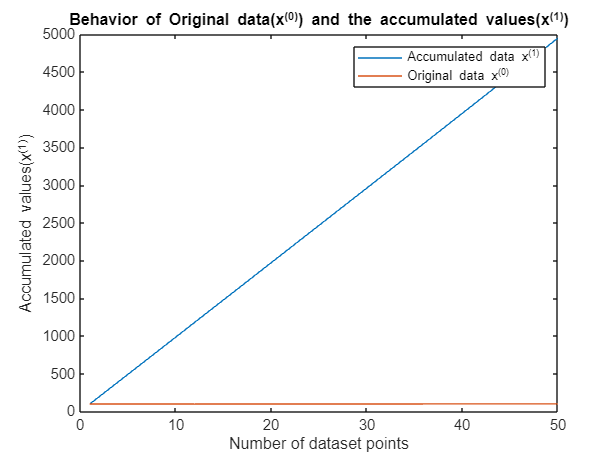

tic
data=readtable("D:\Sem 4\MFC\Project\MFC datasets\Preonzo Landslide dataset.xlsx");
raw_E1=data.E3;
raw_E1=raw_E1(~isnan(raw_E1));
x0=abs(raw_E1);
x0=abs(x0)';
x1=cumsum(x0);
plot(x1(1:50));xlabel("Number of dataset points");ylabel("Accumulated values(x^{(1)})");title("Behavior of Original data(x^{(0)}) and the accumulated values(x^{(1)})");hold on
plot(x0(1:50));
legend("Accumulated data x^{(1)}","Original data x^{(0)}")
hold off

n=size(x0);
n=n(:,2);

L = 5;
x0_hat_meta = zeros(1,n);
x0_hat_meta(1:L) = x0(1:L);
lambda = 0.6;
lambda_r = 0.1;
a=zeros(1,n);
for t = L+1:n
    x0_win = x0(t-L : t-1);
    x1_win = cumsum(x0_win);
    z1 = lambda * x1_win(2:end) + (1-lambda) * x1_win(1:end-1);
    B = [-z1' ones(L-1,1)];
    Y = x0_win(2:end)';
    theta = (B'*B + lambda_r*eye(2)) \ (B'*Y);
    a(t) = theta(1);
    b = theta(2);
    x1_hat = (x1_win(1) - b/a(t)) * exp(-a(t) * (0:L-1)) + b/a(t);
    x0_hat_meta(t) = x1_hat(end) - x1_hat(end-1);
    Y_hat = B * theta;
    residuals = Y - Y_hat;
    df = (L-1) - 2; 
    sigma_sq = (residuals' * residuals) / df;
    C = sigma_sq * inv(B' * B + lambda_r * eye(2));
    se_a = sqrt(C(1,1));
    se_b = sqrt(C(2,2));
    t_val_a = theta(1) / se_a;
    t_val_b = theta(2) / se_b;
end 
t_val_a

t_val_a = -1.4505

t_val_b

t_val_b = 7.1837

x0=x0(:)';
x0_hat_meta=x0_hat_meta(:)';
res_meta=x0-x0_hat_meta;
E = fft(res_meta);
magE = abs(E);
K=3;
[~, idx] = sort(magE(2:floor(n/2)), 'descend');
idx = idx(1:K) + 1;

E_filt = zeros(size(E));
E_filt(1) = E(1);
E_filt(idx) = E(idx);
E_filt(n-idx+2) = E(n-idx+2);

res_hat_meta = real(ifft(E_filt));

x0_hat_meta_final = x0_hat_meta + res_hat_meta

x0_hat_meta_final = 1.0e+03 *

    0.0794    0.0794    0.0795    0.0794    0.0795    0.0837    0.0838    0.0838    0.0838    0.0838    0.0838    0.0838    0.0839    0.0839    0.0838    0.0839    0.0839    0.0839    0.0840    0.0840    0.0840    0.0841    0.0841    0.0841    0.0841    0.0841    0.0841    0.0841    0.0839    0.0840    0.0841    0.0843    0.0842    0.0842    0.0842    0.0841    0.0843    0.0845    0.0846    0.0847    0.0848    0.0849    0.0849    0.0850    0.0850    0.0850    0.0850    0.0851    0.0851    0.0851


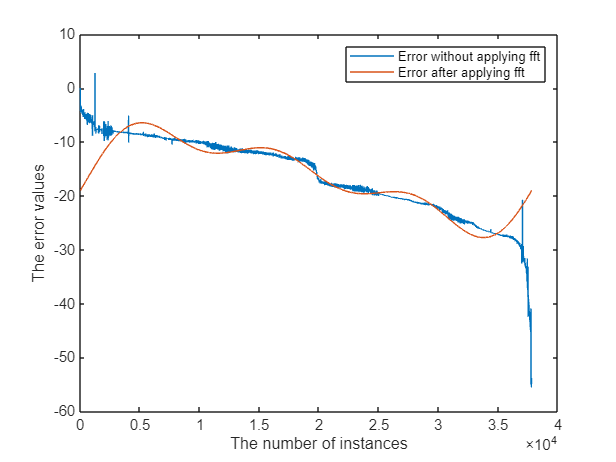

plot(res_meta);hold on
plot(res_hat_meta);legend("Error without applying fft","Error after applying fft");
xlabel("The number of instances");ylabel("The error values");
hold off;

err_meta = x0 - x0_hat_meta_final

err_meta =    19.0077   19.0040   19.0003   18.9965   18.9928   14.8021   14.7727   14.7515   14.7544   14.7492   14.7954   14.8120   14.7109   14.6622   14.8019   14.7156   14.8093   14.7981   14.7426   14.7030   14.7490   14.7169   14.6947   14.6841   14.6833   14.6788   14.6750   14.3713   14.8455   14.7703   14.9514   14.5405   14.5889   14.6671   14.4258   14.9871   14.9013   14.7658   14.7198   14.7552   14.6987   14.6674   14.6576   14.6039   14.5769   14.6184   14.5872   14.5649   14.6043   14.5738


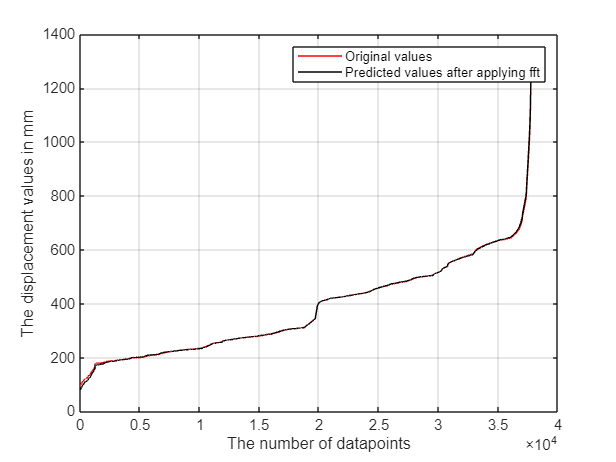

plot(x0,"r");hold on
plot(x0_hat_meta_final,"k");legend("Original values","Predicted values after applying fft");
xlabel("The number of datapoints");ylabel("The displacement values in mm");
hold off
grid on

risk_values_3 = ones(1,n)*1.75;
hazard_level = strings(1,n); 
hazard_level(:) = "No Warning";
RC = 0.001;
RT = 1.75;
for k = 2850:n
    num = abs(x0(k) - x0_hat_meta_final(k));
    den = x0(k);
    p_i = num / den;
    accel_factor = abs(a(k));            
    risk_values_3(k) =(p_i * 100) + (accel_factor * 5);
    if risk_values_3(k) > RT
        
        hazard_level(k) = "Advanced Warning";
    else
        hazard_level(k) = "Safe";
    end
end
risk_values_3 = min(risk_values_3, 20);
hazard_level'

ans = 37822×1 string array
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"


#### The Original Combined Displacement & Risk Plot(With all values considered)

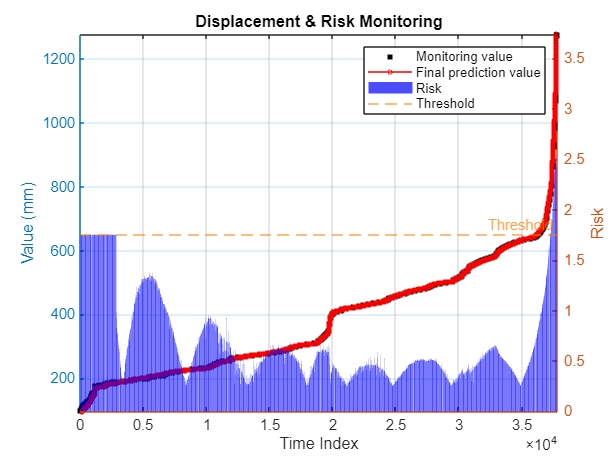

figure;
yyaxis left
plot(x0, 'ks', 'MarkerSize', 4, 'MarkerFaceColor', 'k');
hold on
plot(x0_hat_meta_final, 'r-o', 'MarkerSize', 3);
ylabel('Value (mm)');
ylim([min(x0)-2, max(x0)+2]);
yyaxis right
bar(risk_values_3, 'FaceColor', 'b', 'FaceAlpha', 0.7);
ylabel('Risk');
ylim([0, max(risk_values_3)*1.2]);
hold on
yline(RT, '--', 'Threshold', 'Color', [1 0.5 0]);

xlabel('Time Index');
title('Displacement & Risk Monitoring');

legend('Monitoring value', ...
       'Final prediction value', ...
       'Risk', ...
       'Threshold');

grid on

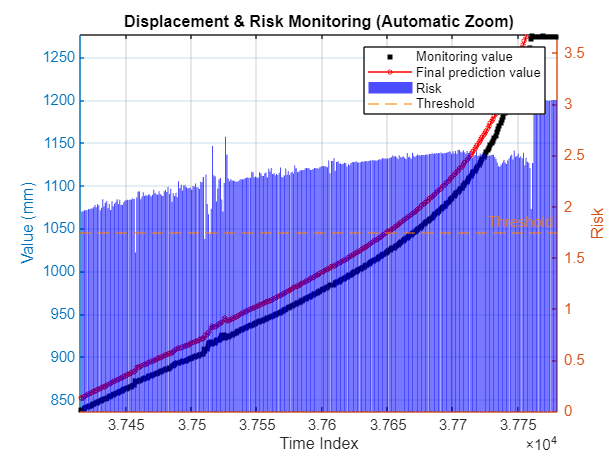

idx = 37416:37779;
idx = idx(idx <= n);

figure;
yyaxis left
plot(idx, x0(idx),'ks','MarkerSize',4,'MarkerFaceColor','k'); hold on
plot(idx, x0_hat_meta_final(idx),'r-o','MarkerSize',3);
ylabel('Value (mm)');
ylim([min(x0(idx))-2 max(x0(idx))+2])
yyaxis right
bar(idx, risk_values_3(idx),'FaceColor','b','FaceAlpha',0.7);
ylabel('Risk');
ylim([0 max(risk_values_3(idx))*1.2])
hold on
yline(RT,'--','Threshold','Color',[1 0.5 0]);
xlabel('Time Index');
title('Displacement & Risk Monitoring (Automatic Zoom)');
legend('Monitoring value','Final prediction value','Risk','Threshold');
grid on

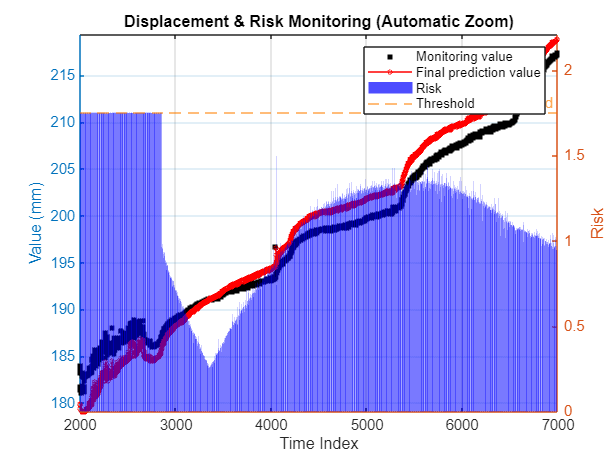

idx = 2000:7000;
idx = idx(idx <= n);

figure;
yyaxis left
plot(idx, x0(idx),'ks','MarkerSize',4,'MarkerFaceColor','k'); hold on
plot(idx, x0_hat_meta_final(idx),'r-o','MarkerSize',3);
ylabel('Value (mm)');
ylim([min(x0(idx))-2 max(x0(idx))+2])
yyaxis right
bar(idx, risk_values_3(idx),'FaceColor','b','FaceAlpha',0.7);
ylabel('Risk');
ylim([0 max(risk_values_3(idx))*1.2])
hold on
yline(RT,'--','Threshold','Color',[1 0.5 0]);

xlabel('Time Index');
title('Displacement & Risk Monitoring (Automatic Zoom)');
legend('Monitoring value','Final prediction value','Risk','Threshold');

grid on

toc

Elapsed time is 3.241025 seconds.


Total time elapsed: `3.241025 seconds.`